# **IO141 - Analog and Digital Loopback**

This example shows you how to do a loopback test with the IO141 I/O module in order to verify the basic functionality of some of the input and output channels.

The IO141 is a 16-bit analog module with 16 single-ended, or 8 differential analog voltage inputs, 4 analog voltage or current outputs and 8 digital TTL I/O lines individually configurable as inputs or outputs.

The Simulink model features the [IO141 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io141_setup), [IO141 Analog input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io141_analog_input), [IO141 Analog output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io141_analog_output), [IO141 Digital input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io141_digital_input) and [IO141 Digital output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io141_digital_output) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO141 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

### Pin Mapping/Connection Diagram/Test Setup

This example outputs a sine wave signal on the analog voltage outputs. The output channels are wired back to the analog input channels where the voltage is measured and displayed in Simulink. 

On the digital part, a pulse generator is connected to the digital outputs. The pulse is sampled with the digital inputs.

On the terminal board of the analog I/O module, connect the analog output pins with the analog input pins, and the digital output pins with the digital input pins. The wiring is shown in the table below:

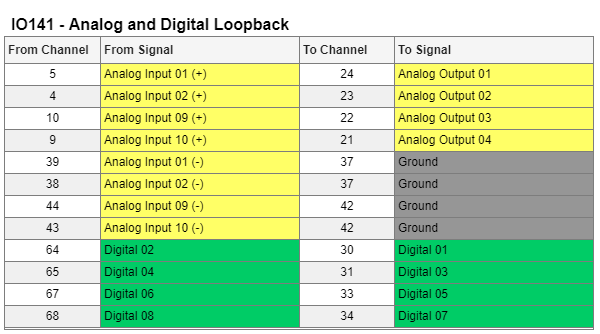

[IO141 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io141_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO141_AnalogDigitalLoopback';
open_system(modelName);

### Model Description

Analog input channels 1 and 3, 9 and 11, and output channels 1, 2, 3 and 4, as well as all 8 digital I/O channels are enabled in the Setup block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

**Analog I/O Loopback**

In the analog input scope you can see the four sine signals sent from analog output channels 1, 2, 3 and 4 to analog input channels 1, 3, 9 and 11 respectively.

The gains used for the analog output signals indicate the different channels seen in the scope (2 V, 4 V, 6 V, 8 V).

The different phase and amplitude shifts are introduced to enhance the visibility of the different channels.

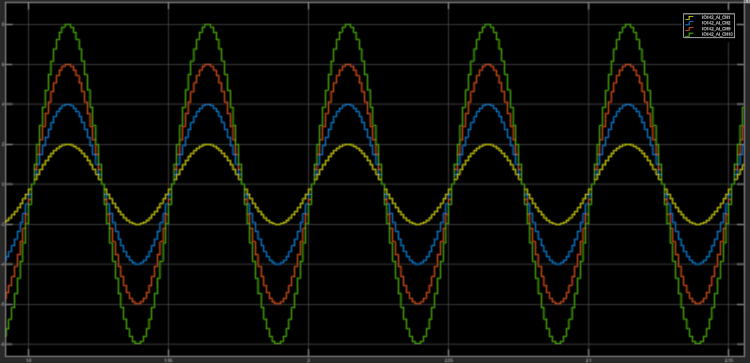

**Digital I/O Loopback**

In the digital input scope you can see the four pulse generator signals sent from digital output channels 2, 4, 6 and 8 to digital input channels 1, 3, 5 and 7 respectively.

The different duty cycles and the y-axis shift are introduced to enhance the visibility of the different channels.

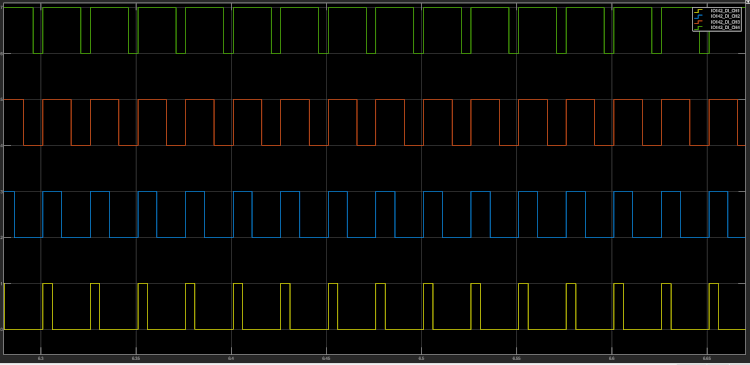

## Additional References

- [IO141 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io141)